file = 'potdng';

%ims = zeros(4, 2000-16, 1500-16, 3, 'single');
ims = zeros(4, 2000-24, 1500-24, 3, 'single');

for x=0:1:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = imread(strcat('cut/', file, deg, '.tif'));
end
clear x;
clear deg;

ims = rgb2lin(ims / 255.0);

imsfft = fft(ims, 4, 1) * 0.5;

imsfftmean = squeeze(imsfft(1, :, :, :)) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
imsfftcosine = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)

%Garden
imsfft = imsfft(:, 101:1900, :, :);
imsfftmean = imsfftmean(101:1900, :, :);
imsfftcosine = imsfftcosine(101:1900, :, :);

%Outside
imsfft = imsfft(:, 501:1200, 301:1200, :);
imsfftmean = imsfftmean(501:1200, 301:1200, :);
imsfftcosine = imsfftcosine(501:1200, 301:1200, :);

%Inside
imsfft = imsfft(:, 301:1500, 101:1000, :);
imsfftmean = imsfftmean(301:1500, 101:1000, :);
imsfftcosine = imsfftcosine(301:1500, 101:1000, :);

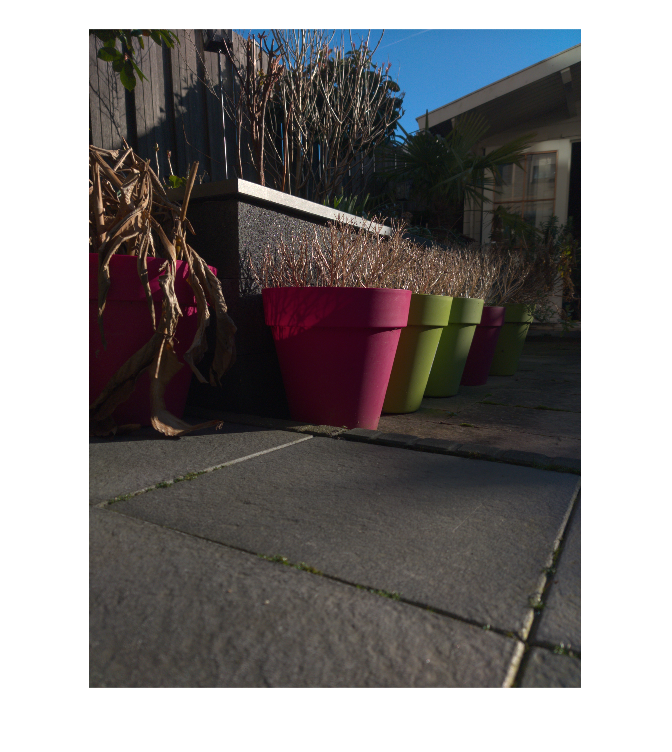

Imax = imsfftmean + imsfftcosine;
Imin = imsfftmean - imsfftcosine;

imshow(lin2rgb(Imax));

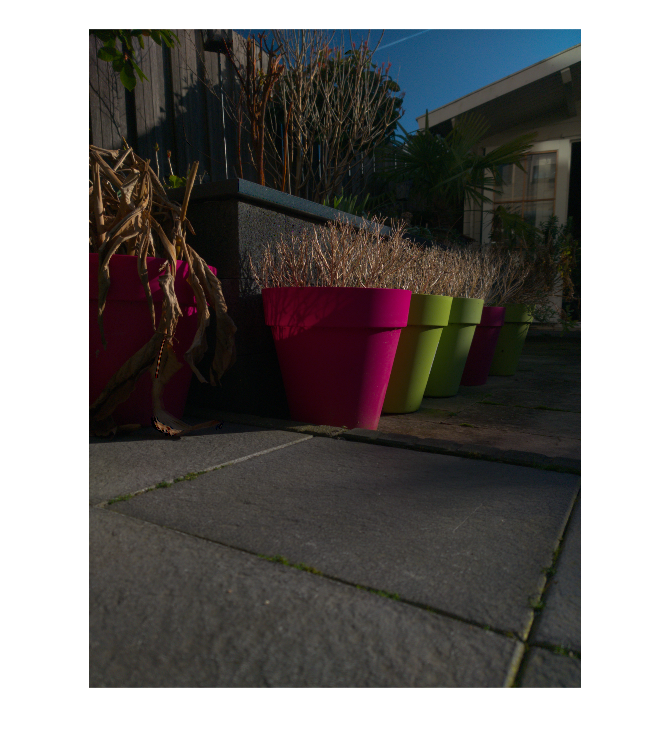

imshow(lin2rgb(Imin));

PolarDiff = 2.0 * imsfftcosine; % Perp - Par
PolarRatio = 3.0; % Assumption: Perp = Ratio * Par
Par = PolarDiff ./ (PolarRatio - 1.0);
Perp = Par + PolarDiff;
Spec = 0.5 * (Par + Perp); % Par + 0.5 * PolarDiff

Diffuse = imsfftmean - Spec; % 0.5 * Diffuse
imwrite(uint8(255.0 * lin2rgb(imsfftmean)), strcat('out/', file, int2str(uint8(PolarRatio * 10)), 'acombine', '.tif'));
imwrite(uint8(255.0 * lin2rgb(Diffuse)), strcat('out/', file, int2str(uint8(PolarRatio * 10)), 'bdiffuse', '.tif'));
imwrite(uint8(255.0 * lin2rgb(Spec)), strcat('out/', file, int2str(uint8(PolarRatio * 10)), 'cspec', '.tif'));
imwrite(uint8(255.0 * lin2rgb(Spec ./ (imsfftmean + 0.01))), strcat('out/', file, int2str(uint8(PolarRatio * 10)), 'dfactor', '.tif'));
imwrite(uint8(255.0 * lin2rgb(Diffuse + 5 * Spec)), strcat('out/', file, int2str(uint8(PolarRatio * 10)), 'eextreme', '.tif'));

% The important part: Finding the actual diffuse and specular components.

% 3 Components: Diffuse, Specular Perpendicular, Specular Parallel

% imsfftmean = 0.5 * Diffuse + 0.5 * (Perp + Par) (truth)
% imsfftcosine = 0.5 * (Perp - Par) (truth)

% Always non-negative, because all components are positive.
%ProjOntoCosine = dot(imsfftcosine, imsfftmean, 3) ./ sum(imsfftcosine .^ 2, 3);

% The initial diffuse guess.
HighestSpecularFactor = 9.0; % Fresnel ratio of 1.25.
LowestSpecularFactor = 1.05; % Fresnel ratio of 40.
%LowestSpecularFactor = 1.5; % Fresnel ratio of 4.
% ProjOntoCosineIter = How many times cos amp from diffuse to avg spec.
ProjOntoCosineIter = min(imsfftmean ./ max(0.001, imsfftcosine), [], 3);

% First iteration: Clip to planes.
%PolarMeanRemains = imsfftmean ./ max(0.001, imsfftcosine) - ProjOntoCosineIter;
%RemainsFactor = min(PolarMeanRemains, [], 3);
%ProjOntoCosineIter = ProjOntoCosineIter + min(0.0, RemainsFactor);

IterCount = 8;
for i = 1:IterCount
    % ProjOntoCosineVec = 0.5 * (Par + Perp) (estimation)
    ProjOntoCosineVec = ProjOntoCosineIter .* imsfftcosine;
    
    % PolarMeanRemains = 0.5 * Diffuse (estimation)
    PolarMeanRemains = imsfftmean - ProjOntoCosineVec;
    
    imwrite(uint8(255.0 .* lin2rgb(max(0, PolarMeanRemains))), strcat('iter/', file, 'diffuse', int2str(i), '.tif'));
    imwrite(uint8(255.0 .* lin2rgb(ProjOntoCosineVec)), strcat('iter/', file, 'specular', int2str(i), '.tif'));
    
    if i == IterCount
        break
    end
    
    % Every iteration Par becomes closer to 0, but cannot become 0 due to LowestSpecularFactor.
    %Perp = ProjOntoCosineVec + imsfftcosine;
    %Par = ProjOntoCosineVec - imsfftcosine;
    %FresnelRatio = Perp ./ Par;
    % No point in working with vectors when they are all in the same 1D subspace.
    Perp = ProjOntoCosineIter + 1.0;
    Par = ProjOntoCosineIter - 1.0;
    FresnelRatio = Perp ./ Par;
    
    %imwrite(uint8(255.0 .* lin2rgb(Perp .* imsfftcosine)), strcat('iter/', file, 'perp', int2str(i), '.tif'));
    %imwrite(uint8(255.0 .* lin2rgb(Par .* imsfftcosine)), strcat('iter/', file, 'par', int2str(i), '.tif'));
    imwrite(uint8(255.0 .* lin2rgb(min(1, FresnelRatio / 40))), strcat('iter/', file, 'ratio', int2str(i), '.tif'));
    
    % Update ProjOntoCosineIter by reducing it.
    
    % FresnelRatio -> ProjOntoCosineIter
    % FresnelRatio = Perp / Par
    % imsfftcosine = 0.5 * (Perp - Par)
    % ProjOntoCosineIter = (Perp / imsfftcosine) - 1.0
    
    % Clip to reasonable values.
    ProjOntoCosineIter = max(LowestSpecularFactor, ProjOntoCosineIter);
    ProjOntoCosineIter = min(HighestSpecularFactor, ProjOntoCosineIter);
    
%     norma = @(a) a ./ vecnorm(a, 2, 3);
%     
%     ProjOntoCosineIter2 = zeros(size(ProjOntoCosineIter) - 2);
%     ProjOntoCosineWeight2 = ProjOntoCosineIter2;
%     for dy = -1:1
%         for dx = -1:1
%             ShiftVec = PolarMeanRemains((2:end-1) + dy, (2:end-1) + dx, :);
%             ShiftIter = ProjOntoCosineIter((2:end-1) + dy, (2:end-1) + dx);
%             
%             ds = norm([dx dy]) / 0.75; % Space.
%             GaussWeight = exp(-0.5 * ds .^ 2);
%             
%             dc = vecnorm(norma(ShiftVec) - norma(PolarMeanRemains(2:end-1, 2:end-1, :)), 2, 3) / 0.75; % Color
%             GaussWeight2 = exp(-0.5 * dc .^ 2);
%             
%             GaussWeight3 = max(0.1, 4.0 - ShiftIter);
%             
%             %ShiftWeight = max(0.0, dot(norma(ShiftVec), norma(PolarMeanRemains(2:end-1, 2:end-1, :)), 3));
%             %ShiftWeight = max(0.0, 0.001 + dot(ShiftVec, PolarMeanRemains(2:end-1, 2:end-1, :), 3));
%             %ShiftWeight = ShiftWeight ./ max(0.001, ShiftIter .^ 4); % Higher weight to lower cosine amounts.
%             %ShiftWeight = ShiftWeight .* GaussWeight;
%             %ShiftWeight = 1.0 ./ (0.01 + mean(abs(ShiftVec - PolarMeanRemains(2:end-1, 2:end-1, :)), 3));
%             
%             ShiftWeight = GaussWeight .* GaussWeight2 .* GaussWeight3;
%             
%             ProjOntoCosineIter2 = ProjOntoCosineIter2 + ShiftWeight .* ShiftIter;
%             ProjOntoCosineWeight2 = ProjOntoCosineWeight2 + ShiftWeight;
%         end
%     end
%     ProjOntoCosineIter(2:end-1, 2:end-1) = ProjOntoCosineIter2 ./ ProjOntoCosineWeight2;
    
    %ProjOntoCosineIter = imdilate(ProjOntoCosineIter, [0 1 0; 1 1 1; 0 1 0]);
    %ProjOntoCosineIter = max(LowestSpecularFactor, ProjOntoCosineIter .* 0.75);
end

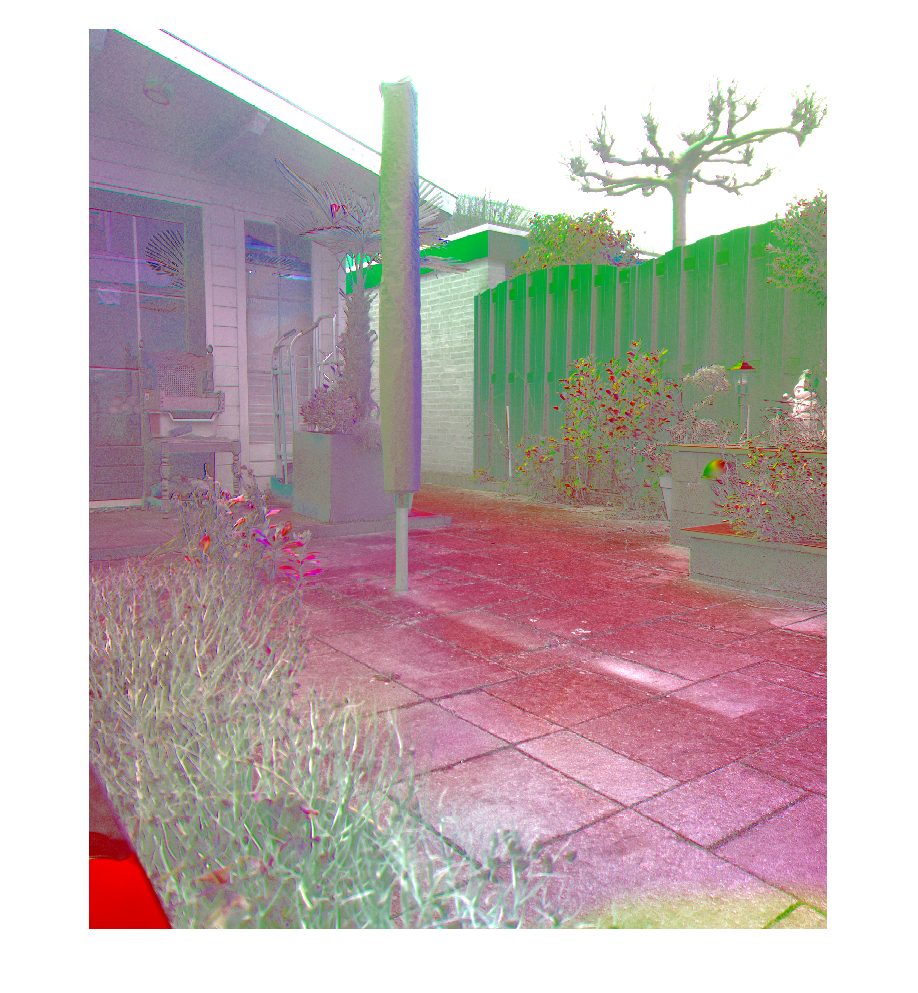

% Polarization Map

HSV = zeros(size(imsfftmean));

WhiteChannelMean = mean(squeeze(imsfft(1, :, :, :)), 3);
WhiteChannelCosine = mean(squeeze(imsfft(2, :, :, :)), 3);

HSV(:, :, 1) = (angle(WhiteChannelCosine) ./ pi + 1.0) ./ 2.0;
HSV(:, :, 2) = 4 .* abs(WhiteChannelCosine) ./ abs(WhiteChannelMean);
HSV(:, :, 3) = 0.5 + 0.5 * WhiteChannelMean;

RGB = hsv2rgb(HSV);

imshow(RGB);

imwrite(uint8(255.0 * RGB), strcat('out/', file, 'fppolar', '.tif'));

%imshow(lin2rgb(imsfftmean));
%imshow(lin2rgb(5 * imsfftcosine));
%imshow(lin2rgb(imsfftmean - 4 * imsfftcosine));

imwrite(uint8(255.0 * lin2rgb(imsfftmean)), strcat('out/', file, 'amean.tif'));
imwrite(uint8(255.0 * lin2rgb(imsfftmean - imsfftcosine)), strcat('out/', file, 'bnospec.tif'));
imwrite(uint8(255.0 * lin2rgb(imsfftcosine)), strcat('out/', file, 'ccos.tif'));
%imwrite(uint8(255.0 * lin2rgb(imsfftmean - 2 * imsfftcosine)), strcat('out/', file, 'nospec4.tif'));
%imwrite(uint8(255.0 * lin2rgb(imsfftmean + 8 * imsfftcosine)), strcat('out/', file, 'xspec2.tif'));

%imwrite(uint8(255.0 * lin2rgb(0.01 * (imsfftmean + imsfftcosine) ./ (imsfftmean - imsfftcosine))), strcat('out/', file, 'fresnel.tif'));
imwrite(uint8(255.0 * lin2rgb(imsfftcosine ./ (imsfftmean + 0.01))), strcat('out/', file, 'ddiv.tif'));


S0 = squeeze(ims(1, :, :, :) + ims(3, :, :, :));
S1 = squeeze(ims(1, :, :, :) - ims(3, :, :, :));
S2 = squeeze(ims(2, :, :, :) - ims(4, :, :, :));

S0sRGB = uint8(255.0 * lin2rgb(S0));
imshow(S0sRGB); % Unpolarized

UnpolarizedI = S0 .^ 2;
PolarizedI = S1 .^ 2 + S2 .^ 2;
Polarization = PolarizedI ./ UnpolarizedI;

for i = 1:3
    Polarization(:, :, i) = medfilt2(Polarization(:, :, i), [5 5]);
end

PolarizationsRGB = uint8(255.0 * Polarization);

imshow(PolarizationsRGB);
imshow(rgb2gray(PolarizationsRGB));

imwrite(PolarizationsRGB, strcat('out/', file, 'polar.tif'));
imwrite(rgb2gray(PolarizationsRGB), strcat('out/', file, 'polargray.tif'));

% ims = 255.0 * lin2rgb(ims);

DepolarizedsRGB = uint8(255.0 * (S0 - sqrt(PolarizedI)));
imshow(DepolarizedsRGB);
imwrite(DepolarizedsRGB, strcat('out/', file, '0polar.tif'));

NormalpolarizedsRGB = uint8(255.0 * (S0));
imshow(NormalpolarizedsRGB);
imwrite(NormalpolarizedsRGB, strcat('out/', file, '1polar.tif'));

ExtrapolarizedsRGB = uint8(255.0 * (S0 + sqrt(PolarizedI)));
imshow(ExtrapolarizedsRGB);
imwrite(ExtrapolarizedsRGB, strcat('out/', file, '2polar.tif'));

OnlypolarizedsRGB = uint8(255.0 * (5 * sqrt(PolarizedI)));
imshow(OnlypolarizedsRGB);
imwrite(OnlypolarizedsRGB, strcat('out/', file, 'xpolar.tif'));

BlendpolarizedsRGB = uint8(255.0 * (0.25 * S0 + 4 * sqrt(PolarizedI)));
imshow(BlendpolarizedsRGB);
imwrite(BlendpolarizedsRGB, strcat('out/', file, 'bpolar.tif'));